## GLEcustom_v13 Intro

This scrip is about to research about the meating time of two particular genetic locus. And in this scrip I will use a new kind of random force. In case of the unreliable result of v9 (1 dimension scrip), in this scrip we use 3 dimension. And i change the intensity of fbm.

And in order to expedite the scrip, i ignore part of the early history in GLE equation.

## FPT v0 Intro

I try to adapt the v13 scrip, for there are several problems, for example, the distance when t=0, and delete the "ignored" function.

## Data Importing

import parameters

a1=[6.0727E-9,0.5127,2.0212E-8,0.69714];
m=a1(1);%just for test
psi=a1(2);%psi=0---> no potential
zeta=a1(3);
H=a1(4);
kB=1.3806505e-23;
T=293;
meeting_distance=5e-8;

import Time interval

delta=0.1;

import Total Time

Tmax=500;
imax=Tmax/delta;

import Total_experiment_number

Total_experiment_number=100000;

import distribution intervals

distribution_interval=10;

## Random Force

We create the random force in this part and smooth it.

The interval of each point is delta

%BH=wfbm(H,imax+1);
%X=1:imax;
%x_length = linspace(1,Tmax);
%BHt=interp1(X,BH(2:imax+1),x_length,'pchip');%smooth the random
%plot(x_length,BHt)%draw the figure to verify

## Initialization

initialization v, x, and a data type

v=zeros(3,imax+1);
x=zeros(3,imax+1);
a=zeros(3,imax+1);
BH=zeros(3,imax+1);%may be imax+2 
first_passage_step=zeros(Total_experiment_number,1);

## Main loop

initialization v, x, and a when t =0

for n=1:Total_experiment_number
    for k=1:3
        v(k,1)=normrnd(0,(kB*T/m)^0.5);%should be random
        x(k,1)=normrnd(0,(kB*T/(m*psi))^0.5);%should be random
        a(k,1)=0;%no need to be random
        BH(k,:)=(delta^H)*wfbm(H,imax+1);
    end
    for i=1:imax
        KH=i:-1:1;
        for k=1:3
            x(k,i+1)=x(k,i)+v(k,i)*delta;
            v(k,i+1)=v(k,i)+a(k,i)*delta;
            a(k,i+1)=-(zeta/m)*2*H*(2*H-1)*delta^(2*H-2)*((KH.^(2*H-2))*v(k,1:i)')*delta-psi*x(k,i)+(2*zeta*kB*T)^0.5*(BH(k,i+1)-BH(k,i))/(m*delta);%ODE
        end
        if x(1,i+1)^2+x(2,i+1)^2+x(3,i+1)^2<=meeting_distance^2
            break
        end
    end

monitoring the progress rate

    progress_rate=n/Total_experiment_number*100;
    if i~=imax
        first_passage_step(n,1)=i;%means betwean t=(i-1)*delta adn t=i*delta
    end
    if progress_rate==floor(progress_rate)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

## Data output

FPT_distripution=zeros(floor(max(first_passage_step)*delta/distribution_interval),1);
max_n_interval=0

max_n_interval = 0

for i=1:Total_experiment_number
    if floor(first_passage_step(i)*delta/distribution_interval)~=floor(max(first_passage_step)*delta/distribution_interval)
        FPT_distripution(floor(first_passage_step(i)*delta/distribution_interval)+1,1)=FPT_distripution(floor(first_passage_step(i)*delta/distribution_interval)+1,1)+1;
        if floor(first_passage_step(i)*delta/distribution_interval)+1>max_n_interval
            max_n_interval=floor(first_passage_step(i)*delta/distribution_interval)+1;
        end
    end
end

## Plotting and saving

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
save([storage_location,'\data\FPT','.m=',num2str(m),'.psi=',num2str(psi),'.zeta=',num2str(zeta),'.H=',num2str(H),'.d=',num2str(meeting_distance),'.N=',num2str(Total_experiment_number),'.mat'],"first_passage_step","FPT_distripution");

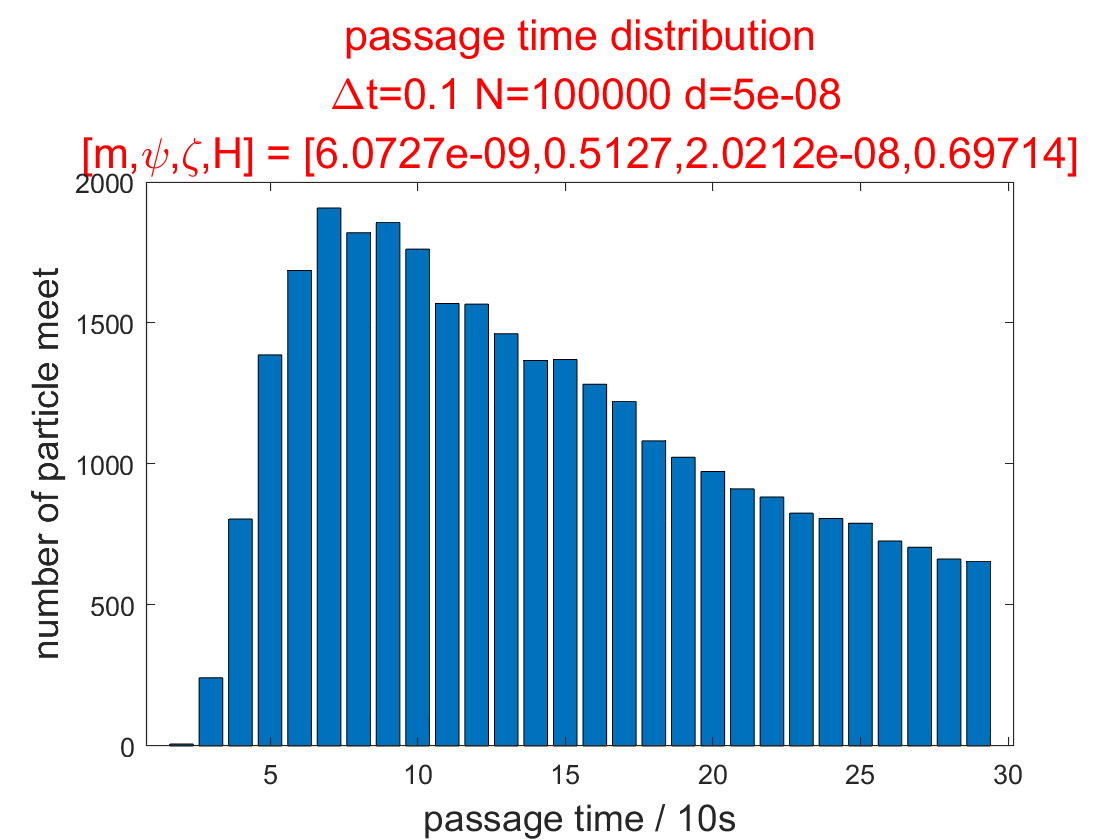

figure
bar(2:max_n_interval,FPT_distripution(2:max_n_interval,1));
%set(gca,'yscale','log');
xlabel(['passage time / ',num2str(distribution_interval),'s'],'FontSize',14);
ylabel('number of particle meet','FontSize',14);
title({'passage time distribution',[' \Deltat=',num2str(delta),' N=',num2str(Total_experiment_number),' d=',num2str(meeting_distance)],['[m,\psi,\zeta,H] = [',num2str(m),',',num2str(psi),',',num2str(zeta),',',num2str(H),']']},'Color','r','FontSize',16)
saveas(gcf,[storage_location,'\image\FPT_distribution','.m=',num2str(m),'.psi=',num2str(psi),'.zeta=',num2str(zeta),'.H=',num2str(H),'.d=',num2str(meeting_distance),'.N=',num2str(Total_experiment_number),'.jpg']);